# **THE ROLE OF MODELS IN UNDERSTANDING CD8+ T-CELL MEMORY**

*Rustom Antia, Vitaly V. Ganusov and Rafi Ahmed*

    Immunological memory — the ability to ‘remember’ previously encountered pathogens and respond faster on re-exposure — is a central feature of the immune response of vertebrates. We outline how mathematical models have contributed to our understanding of CD8+ T-cell memory. Together with experimental data, models have helped to quantitatively describe and to further our understanding of both the generation of memory after infection with a pathogen and the maintenance of this memory throughout the life of an individual.

**** This MATLAB Live script is prepared for understanding of the paper, and simulate the given examples in paper.

*** This MATLAB live script is preapared for KON424E- *Modeling and Control of Biological Systems *Course, Istanbul Technical University.

## Introduction

    In this article, the mathematical model of the anti-reinfection phenomenon based on ancient Greece is studied. Mathematical model of immunological memory, focusing on CD8+ T-cell responses. CD8+ T-cell memory to a specific pathogen can be divided into phases with different time-scales. as given in figure 1.

- Primary response after exposure to the pathogen and the generation of CD8+ memory T cells

- The maintenance of this population of pathogen-specific ‘memory’ cells for a long time-scale (many years).

- Increase in the number of memory cells after re-exposure to the pathogen, which then provides protection.

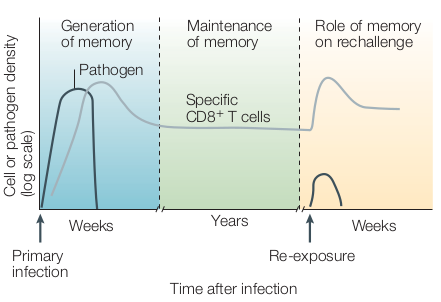

Figure 1

This text explores the use of models to understand CD8+ T-cell behavior, memory lifespan, and their role in protecting against pathogen re-exposure, in next sections.

## Generation of immunological memory

    The primary CD8+ T-cell response to an acute viral infection occurs for a time-scale of a few weeks. It is char- acterized by the rapid clonal expansion (by ∼4–5 log) of virus-specific cells, generating a population of effector cells. After clearance of the infection, there is a clonal contraction (by ∼1–2 log) of this population, leaving a smaller population of virus-specific memory cells.

    Analysis of data on the magnitude of the response to different epitopes, shows that the response can be divided into **clonal-expansion** and **contraction phases**, during which the populations of epitope-specific CD8+ T cells change exponentially.

    Basicly during the clonal-expansion phase, CD8+ T cells increase. In the next step (contraction phases) then include determining the cell-division and cell-death rates. 

***IMMUNODOMINANCE***

*The result of antigen(s) or epitopes within a complex mixture (such as a whole virus) being preferentially recognized or reacted against during an immune response.*

### Measuring cell-division and cell-death rates

    The first estimates of cell-division and cell-death rates of immune cells were obtained using experimental data from the use of **BROMODEOXYURIDINE** (**BrdU**) and ***D-*****glucos** labels, which provide us an estimate of the proportion of a cell population that has undergone division.However, given the limited information that can be obtained from BrdU-labelling studies, the problems that are associated with the interpretation of resultsCurrent approaches include the development of more informative experimental techniques together with the use of more biologically realistic models. Use of CFSE (carboxyfluorescein diacetate succinimidylester) labelling allows the estimation of not only the number of cells that has divided but also the number of divisions each cell has undergone. However, the data obtained from measurements of CFSE levels might be insufficient to estimate all of the parameters of more realistic models

***BROMODEOXYURIDINE (5-Bromo-2-deoxyuridine, BrdU)***

* A thymidine analogue that is incorporated into DNA on replication, allowing tracking of cells that have divided, molecul figure given in 2.*

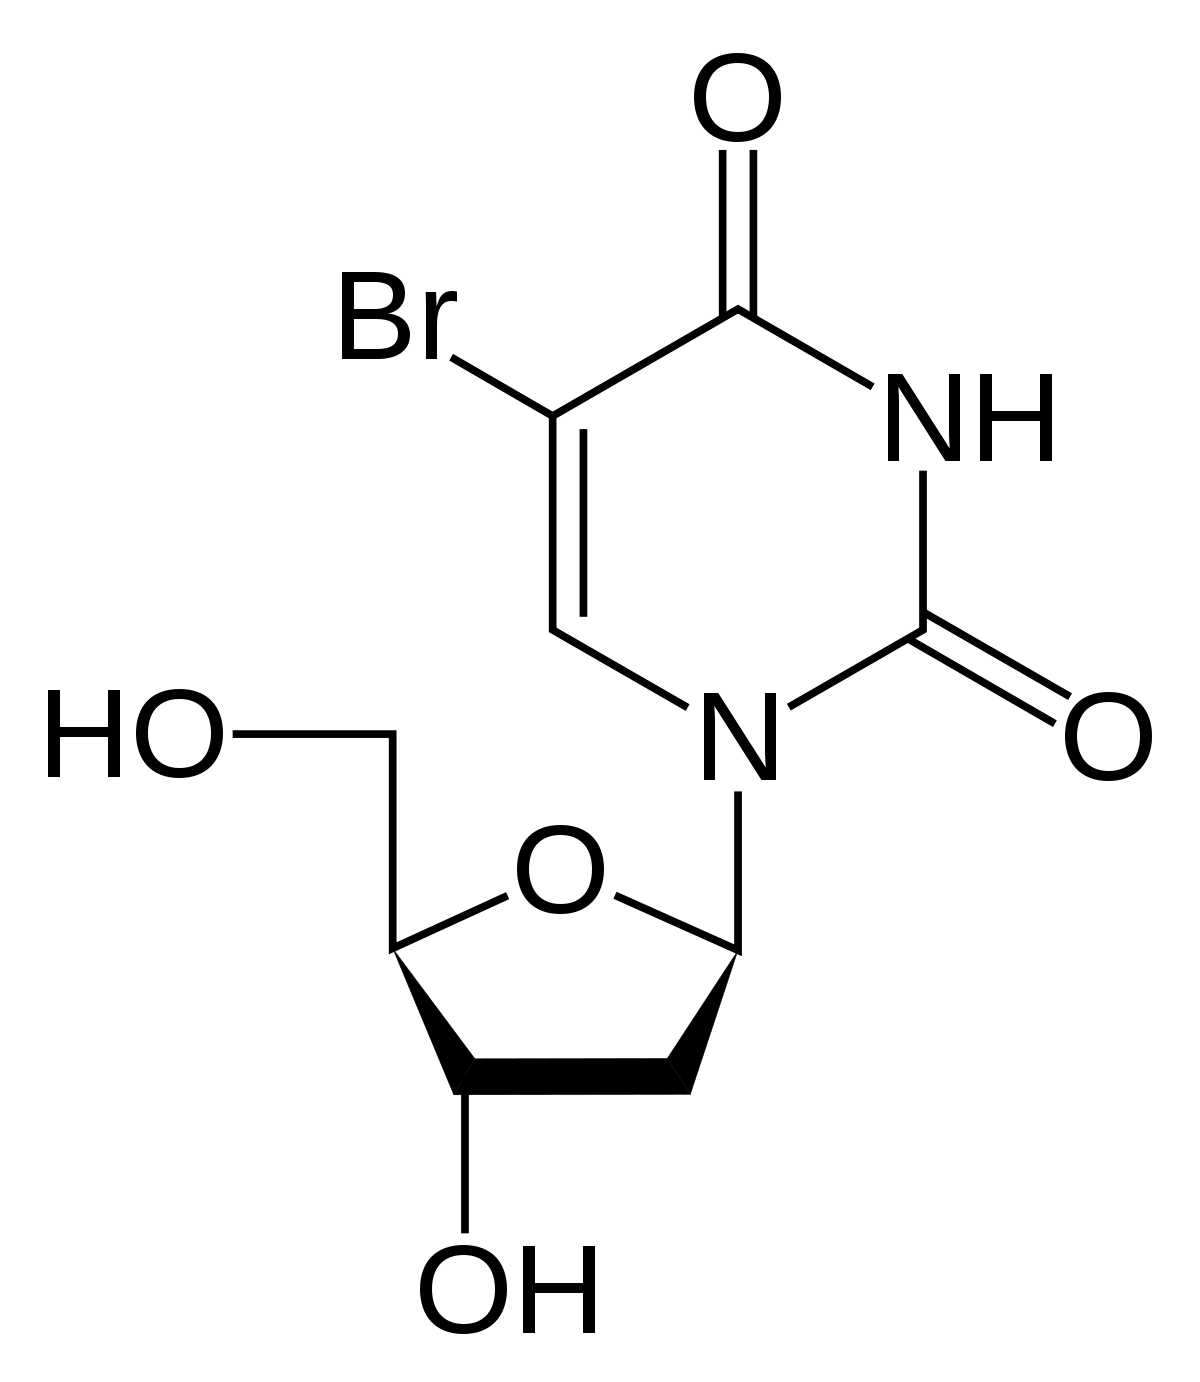

Figure 2, Bromodeoxyuridine -*Wikipedia. 2023. “Bromodeoxyuridine”*

CFSE

*(5,6-Carboxyfluorescein diacetate succinimidyl ester).A membrane-permeable dye that covalently attaches to free amines of cytoplasmic proteins in vitro. After cell division, the concentration of the label halves with each division, allowing eight to ten successive divisions to be tracked by flow cytometry.*

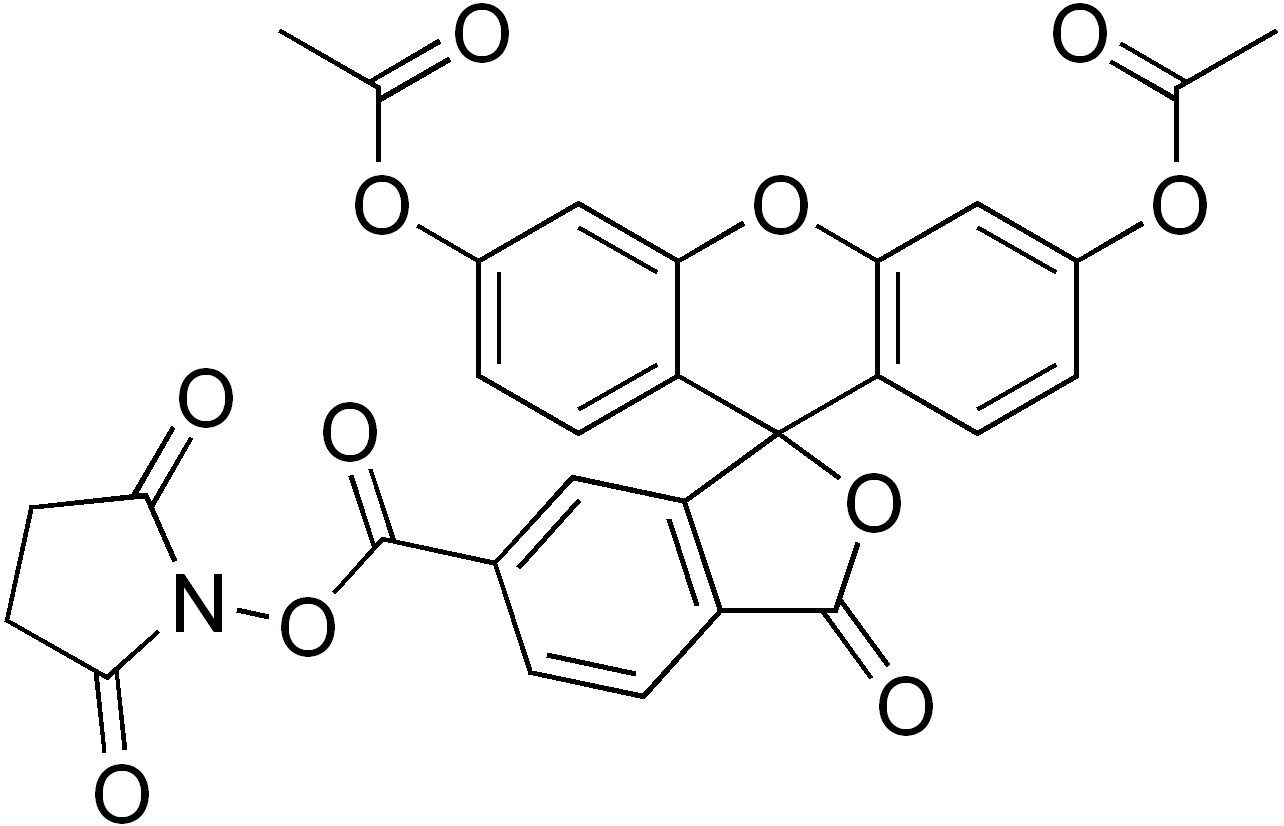

Figure 3, *6-Carboxyfluorescein diacetate succinimidyl ester* -Wikipedia. 2023. “*Carboxyfluorescein diacetate succinimidyl ester*”

### Differentiation of CD8+ T cells into memory T cells

    Mathematical models have also had a role in discrimi nating between different pathways for the differentiation of CD8+ T cells into memory cells during the primary response.There are various hypotheses for the origin of memory cells during the primary response in particular, whether memory cells are generated by the differentiation of effector cells or the converse.Experimental work has shown that cytotoxic effector cells can differentiate into memory T cells and this has been supported by the observation that a model with proliferating effector cells differentiating into memory cells can generate a good fit to the experimental data for biologically reasonable parameters. A frequently used alternative model that involves proliferating memory cells differentiating into non-dividing effector cells cannot generate both the clonal-expansion and -contraction phases for biologically reasonable parameters 

**In the paper more details given in BOX1

# `BOX1`

    There's ongoing debate about the differentiation pathways of CD8+ T cells during a primary immune response, especially the origin of CD8+ memory T cells. This text explores how mathematical models can distinguish between two alternative pathways for the differentiation of antigen-specific CD8+ T cells.

**        1-PE Model**

            PE model, in which memory cells arise from proliferating effector cells.In the PE model, naive cells, N, are recruited into the immune response at time (t) Ton after the infection and give rise to proliferating cells that have effector function, PE . The PE-cell population grows at the rate ρ until time Toff . After this, PE cells either undergo apoptosis at the rate α or differentiate at the rate r to form memory cells, M.

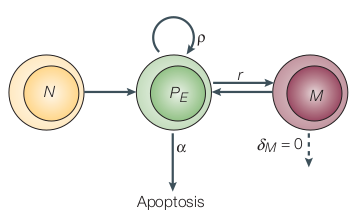

Figure 4


$$\begin{array}{l}
\frac{{d\;P}_{E\;} }{d\;t}=f\left(t\right)\rho P_E -\left\lbrack 1-f\left(t\right)\right\rbrack \left(a+r\right)P_E \\
\frac{d\;M}{d\;t}=r\left\lbrack 1-f\left(t\right)\right\rbrack P_E -\delta_M M\\
\mathrm{Where}\;f\left(t\right)=1,\mathrm{if}\;T_{\mathrm{on}} \le t<T_{\mathrm{off}} \\
f\left(t\right)=0,\mathrm{other}\;\mathrm{wise}
\end{array}$$


        To simulate the model, we have construdted simulink file named "*pm_and_pe_model.slx*". Simulink model given figure below.

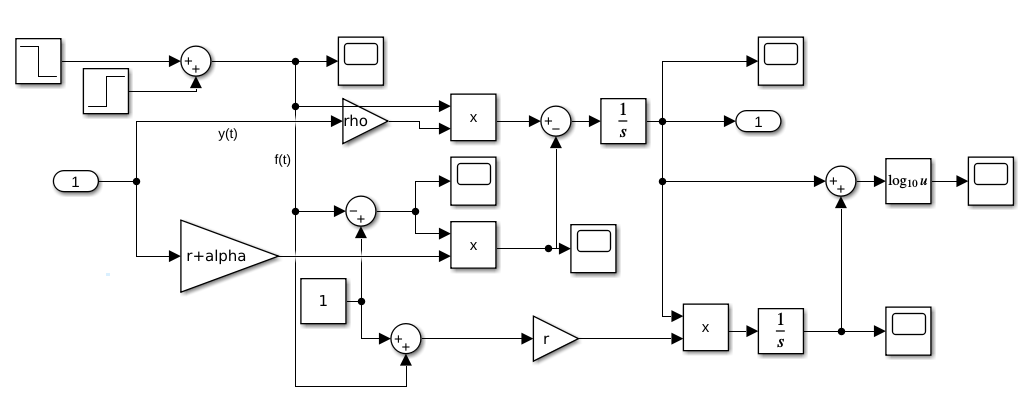

Figure 5 - "*pm_and_pe_model.slx*" Pe subModel

d = 24*60*60;           % the day time in second
N = 100;                % naive cells
Ton = 1.3*d;            % immune responsetime
Toff = 5.9*d;           % effector cell differentiation stops time
r = 0.009*(1/d);        % Differentiation rate of cells
alpha = 0.57*(1/d);     % Apoptosis rate of effector cells
rho = 2.9*(1/d);        % Growth rate of cell populations

% First run the code block, then run tme simulink model

    Figure 6-a shows simulink simulation respond and the figure b presented in the paper. 

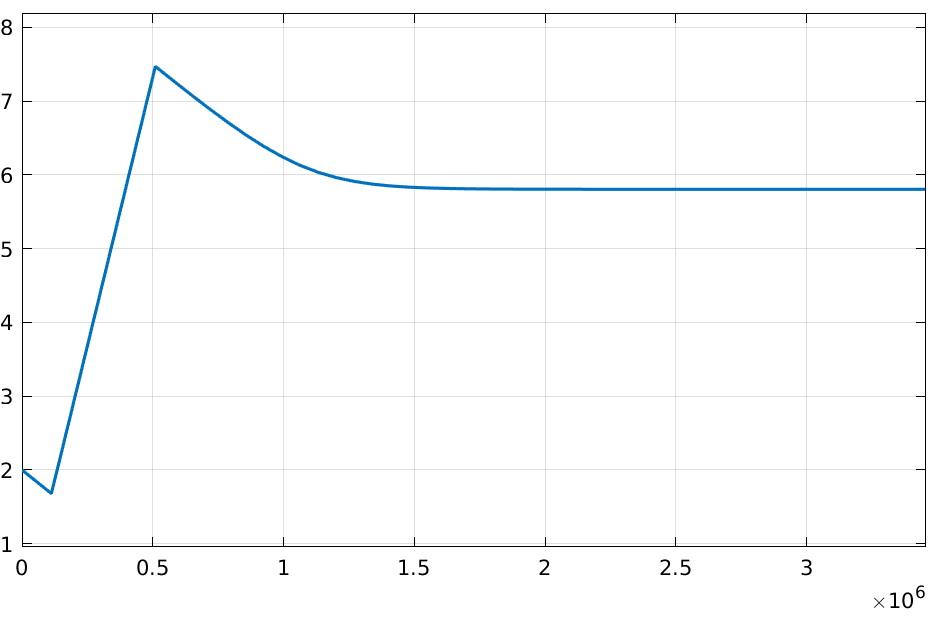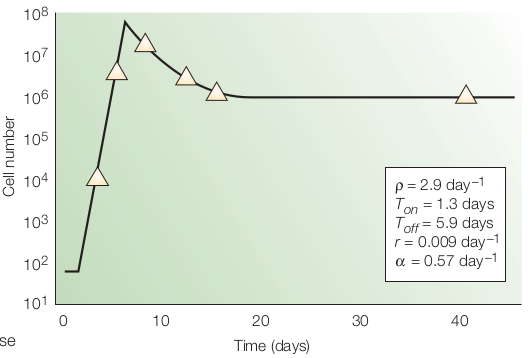

Figure 6, a and b

**        2-PM Model**

In the PM model, the naive-cell population, N, is recruited into the immune response at time Ton after infection, and these cells give rise to proliferating cells that have memory-cell properties, PM . This cell population grows at rate ρ and differentiates into effector cells, E, at rate r until time Toff . After this, E cells undergo apoptosis at rate α. Because of the large amount of data that show the long-term maintenance of memory cell populations in both models, the rate of loss of cells with the memory phenotype (δM) is set to zero

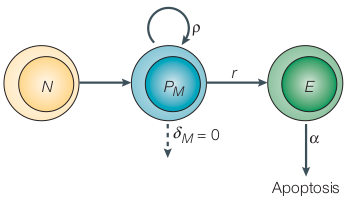

Figure 7


$$\begin{array}{l}
\frac{{d\;P}_{M\;} }{d\;t}=f\left(t\right)\left(\rho -r\right)P_M -\delta_M P_M \\
\frac{d\;E}{d\;t}=rf\left(t\right)P_E -\alpha \left\lbrack 1-f\left(t\right)\right\rbrack E\\
\mathrm{Where}\;f\left(t\right)=1,\mathrm{if}\;T_{\mathrm{on}} \le t<T_{\mathrm{off}} \\
f\left(t\right)=0,\mathrm{other}\;\mathrm{wise}
\end{array}$$


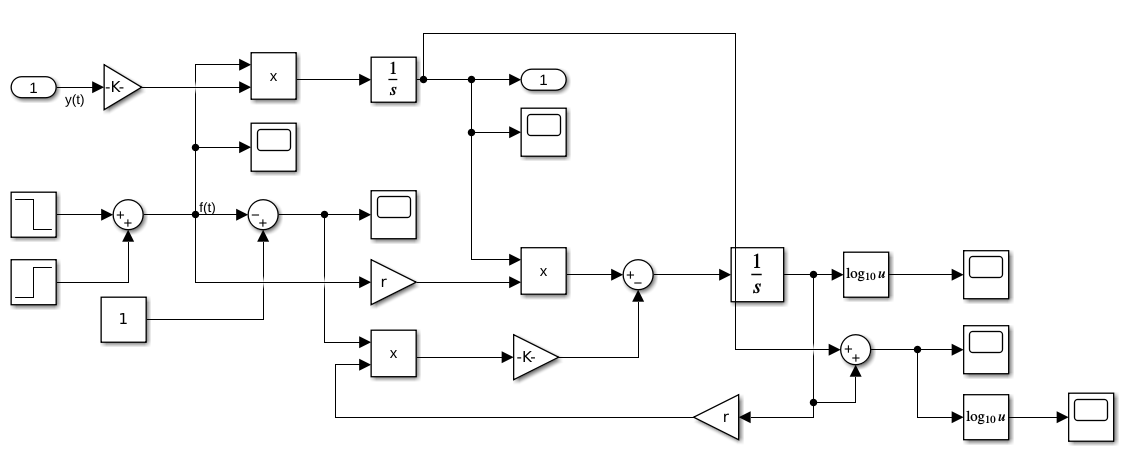

Figure 8 - "*pm_and_pe_model.slx*" PM subModel

d = 24*60*60;           % the day time in second
N = 100;                % naive cells
Ton = 2.54*d;            % immune responsetime
Toff = 5.98*d;           % effector cell differentiation stops time
r = 169.3*(1/d);        % Differentiation rate of cells
alpha = 0.58*(1/d);     % Apoptosis rate of effector cells
rho = 172*(1/d);        % Growth rate of cell populations

% First run the code block, then run tme simulink model


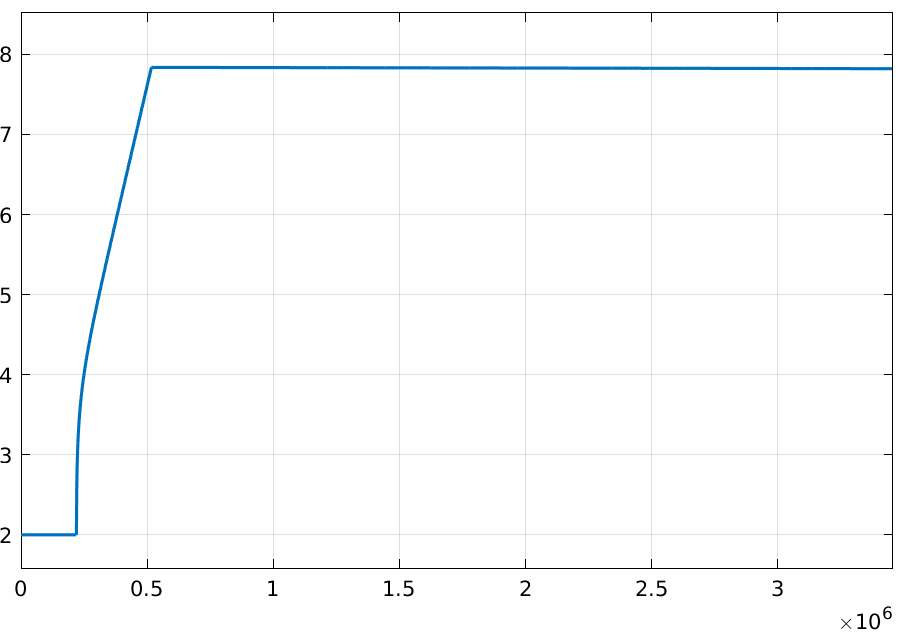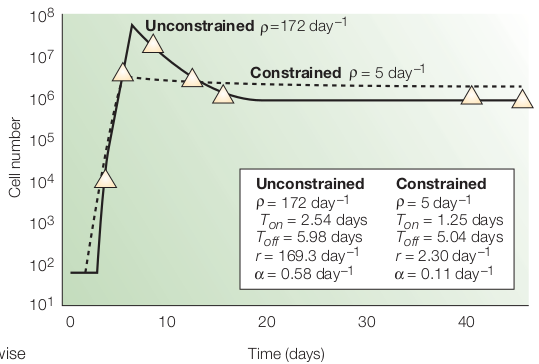

Figure 9, a and b

    Update parameters for constrained

d = 24*60*60;           % the day time in second
N = 100;                % naive cells
Ton = 1.25*d;            % immune responsetime
Toff = 5.04*d;           % effector cell differentiation stops time
r = 2.3*(1/d);        % Differentiation rate of cells
alpha = 0.11*(1/d);     % Apoptosis rate of effector cells
rho = 5*(1/d);        % Growth rate of cell populations

% First run the code block, then run tme simulink model

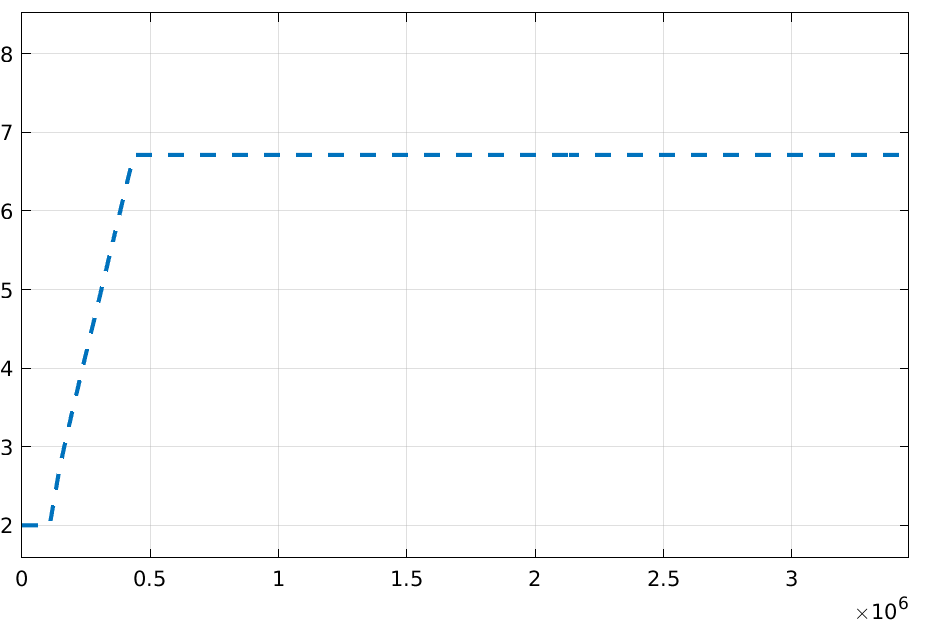

Figure 10, a and b

    We evaluate how well both models describe experimental data using CD8+ T-cell response to the nucleoprotein 118 (NP118) epitope of lymphocytic choriomeningitis virus. The PE model fits the data with biologically reasonable parameter values, while the PM model fails to do so. The PM model requires an unreasonably fast rate constant for T-cell expansion, whereas limiting the maximum growth rate results in the PM model failing to capture the peak and contraction phase of the data. Based on these observations, we reject the PM model and favor the PE model.